% find out name of the rat
thisFolder = pwd;
thisFolderSplitted = strsplit(thisFolder, filesep);
NameIndex =  find(strcmp(thisFolderSplitted, 'ANMs'))+1;
ratName = thisFolderSplitted{NameIndex};

disp(['this rat is: ', ratName]);

this rat is: Undine


savename1 = ['BClassArray_' upper(ratName)];

disp(savename1);

BClassArray_UNDINE


% Read folders
rootFolder = pwd;
files = dir(rootFolder);
dirFlags = [files.isdir];
subFolders = files(dirFlags);
subFolderNames = {subFolders(3:end).name};
dataFolderNames = {};
for k =1:length(subFolderNames)
    if ~isempty(str2num(subFolderNames{k}))
        dataFolderNames = [dataFolderNames  subFolderNames{k}];
        fprintf('Subfolder #%d = %s \n', k,  subFolderNames{k})
    end
end

Subfolder #1 = 20230927 
Subfolder #2 = 20230928 
Subfolder #3 = 20230929 
Subfolder #4 = 20231001 
Subfolder #5 = 20231002 
Subfolder #6 = 20231003 
Subfolder #7 = 20231004 
Subfolder #8 = 20231016 
Subfolder #9 = 20231017 
Subfolder #10 = 20231018 
Subfolder #11 = 20231019 
Subfolder #12 = 20231020 
Subfolder #13 = 20231021 
Subfolder #14 = 20231023 
Subfolder #15 = 20231024 


dataFolderNames'

ans = 15×1 cell 数组
    {'20230927'}
    {'20230928'}
    {'20230929'}
    {'20231001'}
    {'20231002'}
    {'20231003'}
    {'20231004'}
    {'20231016'}
    {'20231017'}
    {'20231018'}
    {'20231019'}
    {'20231020'}
    {'20231021'}
    {'20231023'}
    {'20231024'}


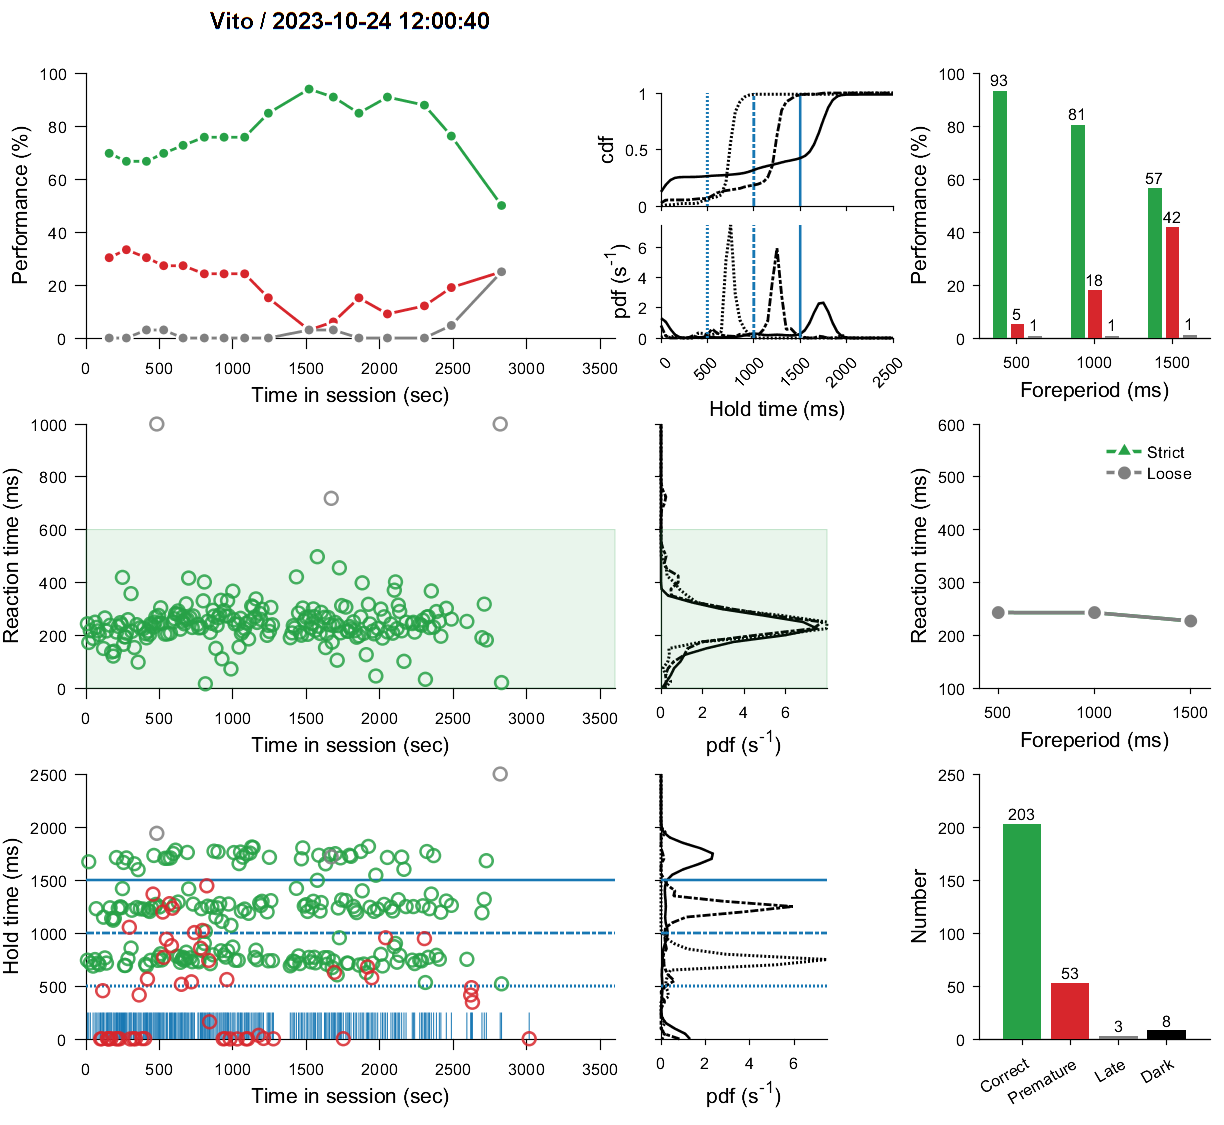

AllSessions = [
    {'20230927'} 'Pre'
    {'20230928'} 'Pre'
    {'20230929'} 'Pre'
    {'20231001'} 'Pre'
    {'20231002'} 'Pre'
    {'20231003'} 'Pre'
    {'20231004'} 'Pre'
    {'20231016'} 'Post'
    {'20231017'} 'Post'
    {'20231018'} 'Post'
    {'20231019'} 'Post'
    {'20231020'} 'Post'
    {'20231021'} 'Post'
    {'20231023'} 'Post'
    {'20231024'} 'Post'
];

BClassArray = cell(1,length(AllSessions));
for i=1:length(AllSessions)
    cd(fullfile(thisFolder, AllSessions{i, 1}))
    iBPOD = dir([ratName '_DSRT*.mat']);
    bc = BehaviorDSRT(iBPOD.name);
    close all;
    
    bc.Group = 'DMS_Lesion';
    bc.Experiment = AllSessions{i, 2};

    bc.plot();
    bc.print();
    BClassArray{i} = bc;
end

cd(thisFolder);
save(savename1, 'BClassArray');

% find out name of the rat
thisFolder = pwd;
thisFolderSplitted = strsplit(thisFolder, filesep);
NameIndex =  find(strcmp(thisFolderSplitted, 'ANMs'))+1;
ratName = thisFolderSplitted{NameIndex};

disp(['this rat is: ', ratName]);

this rat is: Vito


savename1 = ['BClassArray_' upper(ratName)];
disp(savename1);

BClassArray_VITO


close all
load(savename1)
obj = BehaviorDSRT_Indiv(BClassArray); % this is the individual obj. Note that I am using package mode to organize these data

obj.save();
fig = obj.plot('plotType','MixedFP','shadedExp','Post');

No "expName" inputs, use default settings.


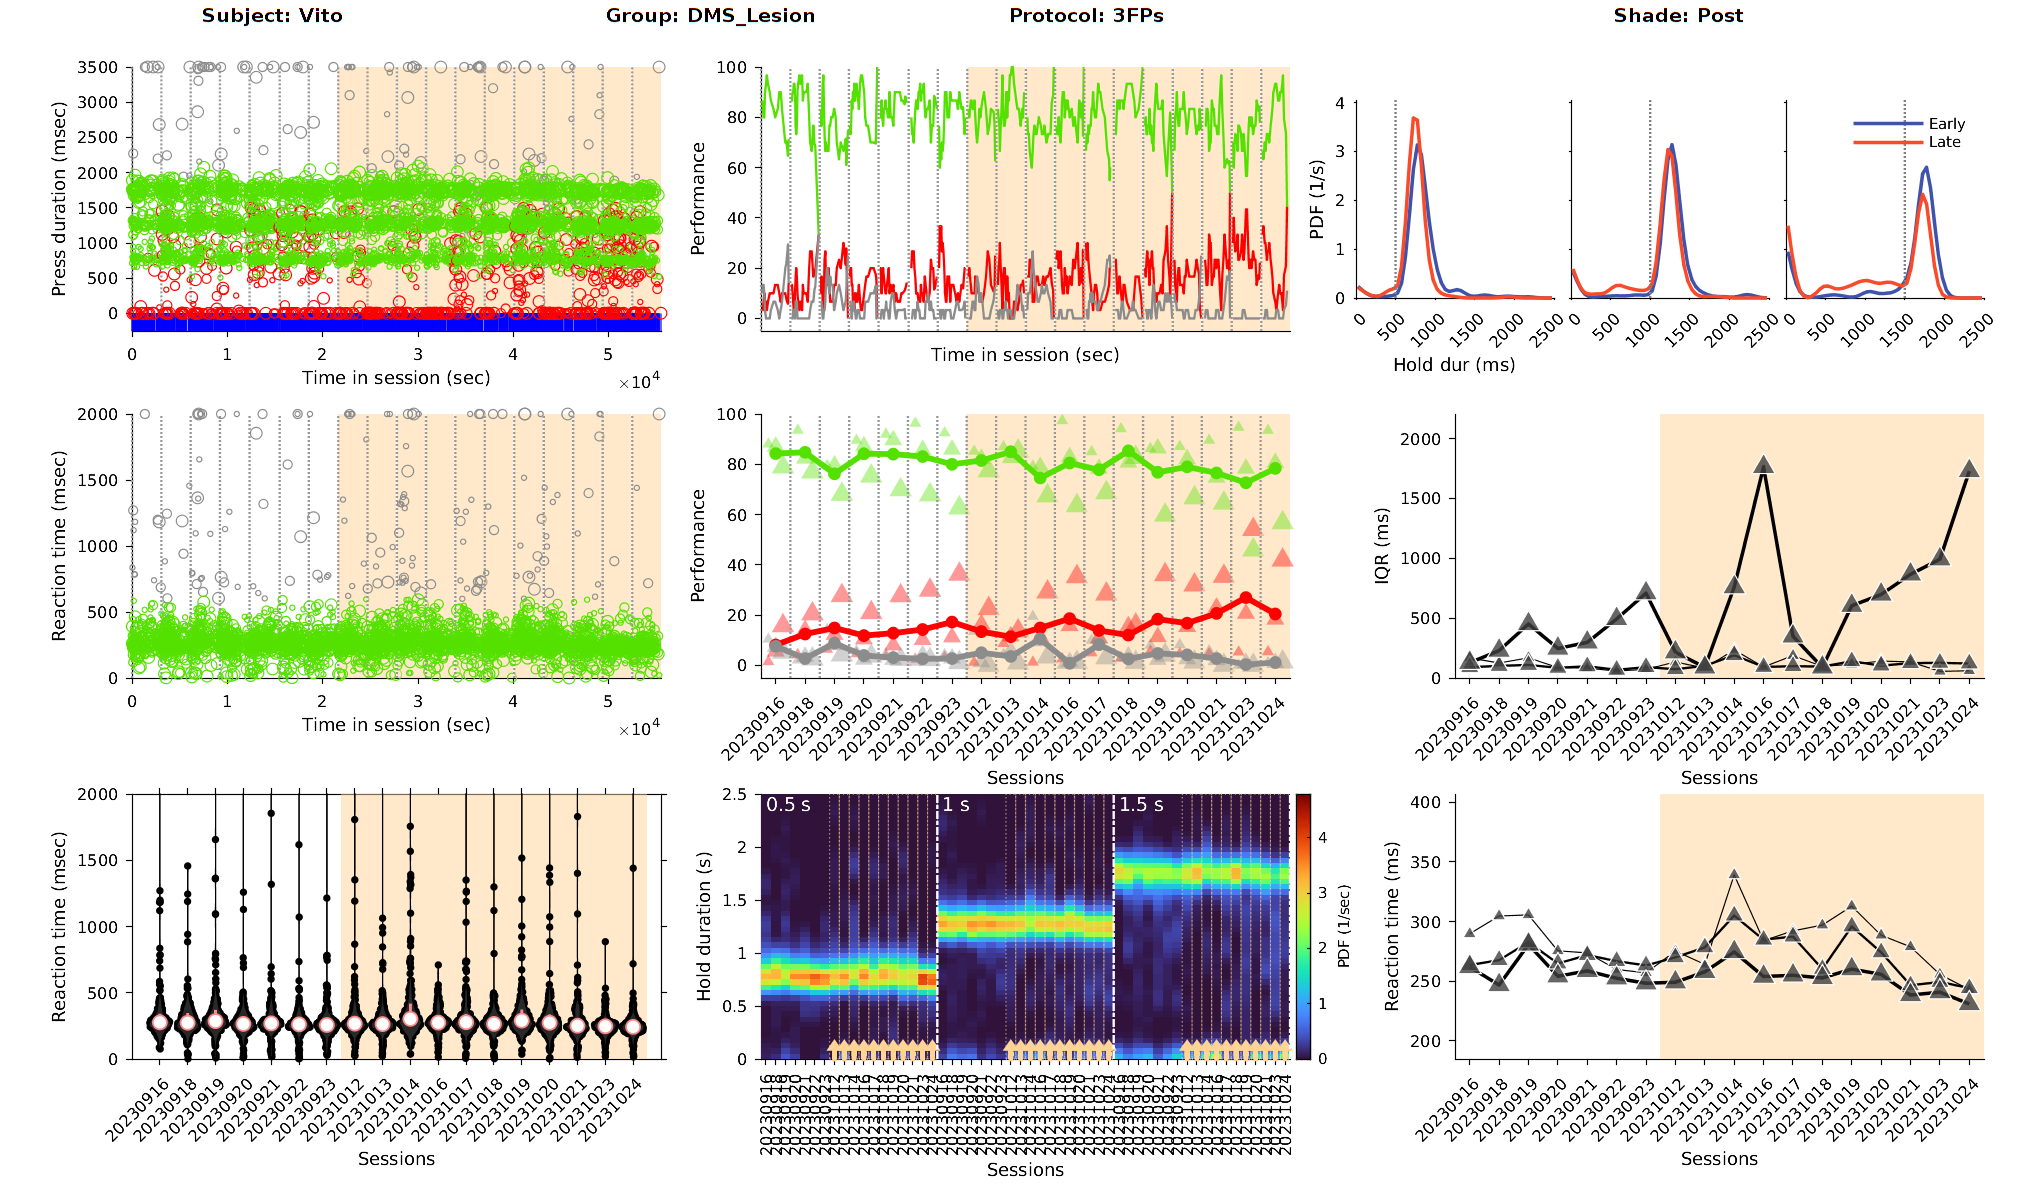

obj.print('tarFig',fig);